# Lab 11 sessió 2

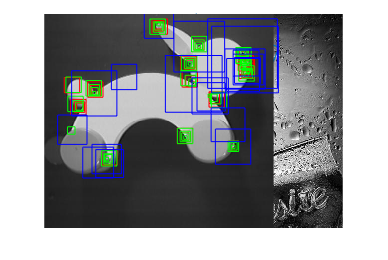

im = imread('rabbit.jpg');
sizes = [7 15 21 31];
imshow(im);

% HARRIS
for j = 1:size(sizes, 2)
    wsize = sizes(j);
    kp = detectHarrisFeatures(im, 'FilterSize', wsize, 'MinQuality', 0.1);
    hold on;
    for i = 1:size(kp, 1)
        rectangle('Position', [kp.Location(i, 1)-wsize/2, kp.Location(i, 2)-wsize/2, ...
            wsize, wsize], 'EdgeColor', 'r');
    end
end

% EIGEN
for j = 1:size(sizes, 2)
    wsize = sizes(j);
    kp = detectMinEigenFeatures(im, 'FilterSize', wsize, 'MinQuality', 0.15);
    hold on;
    for i = 1:size(kp, 1)
        rectangle('Position', [kp.Location(i, 1)-wsize/2, kp.Location(i, 2)-wsize/2, ...
            wsize, wsize], 'EdgeColor', 'g');
    end
end

% FAST
kp = detectFASTFeatures(im, 'MinQuality', 0.1);
hold on;
for i = 1:size(kp, 1)
    wsize = kp.Metric(i);
    rectangle('Position', [kp.Location(i, 1)-wsize/2, kp.Location(i, 2)-wsize/2, ...
        wsize, wsize], 'EdgeColor', 'b');
end

## Detector de contorns

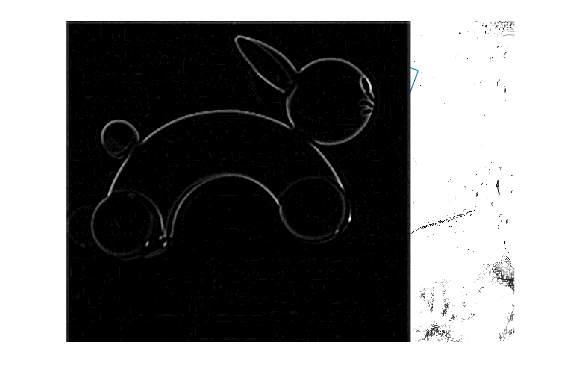

im = imread("rabbit.jpg");

h = fspecial("gaussian", 7, 7/4);
G1 = imfilter(im, h);

h = fspecial("gaussian", 9, 9/4);
G2 = imfilter(im, h);

imshow(G1 - G2, [])

## Detecció per SIFT i RANSAC

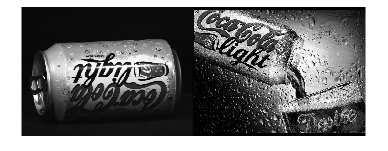

% Carreguem les imatges
im_obj = rgb2gray(imread("coke.jpg"));
im_esc = rgb2gray(imread("anunci.jpg"));

% Les visualitzem
montage({im_obj, im_esc});

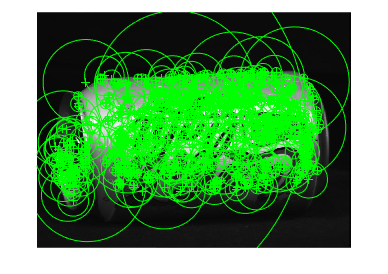


% Detectem features per SIFT
kp_obj = detectSIFTFeatures(im_obj);
kp_esc = detectSIFTFeatures(im_esc);

% Filtrem pels més "forts"
%kp_obj = selectStrongest(kp_obj, 30);
%kp_esc = selectStrongest(kp_esc, 200);

% Visualitzem els punts trobats a les dues imatges
figure, imshow(im_obj);
hold on;
plot(kp_obj);
hold off

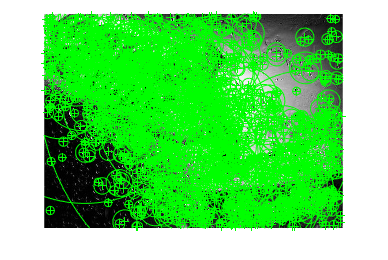

figure, imshow(im_esc);
hold on;
plot(kp_esc);
hold off;

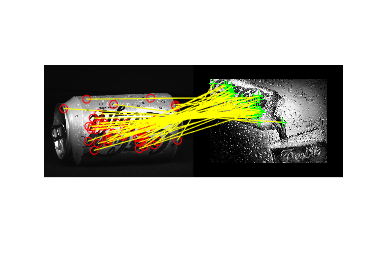



[feat_obj, kp_obj] = extractFeatures(im_obj, kp_obj);
[feat_esc, kp_esc] = extractFeatures(im_esc, kp_esc);

pairs = matchFeatures(feat_obj, feat_esc, "MatchThreshold", 10);

m_kp_obj = kp_obj(pairs(:, 1), :);
m_kp_esc = kp_esc(pairs(:, 2), :);

showMatchedFeatures(im_obj, im_esc, m_kp_obj, m_kp_esc, "montage")

[T] = estimateGeometricTransform2D(m_kp_obj, m_kp_esc, "affine");

[f_obj, c_obj] = size(im_obj);

box = [1, 100; c_obj, 100; c_obj, f_obj; 1, f_obj; 1, 100];
figure, imshow(im_obj)

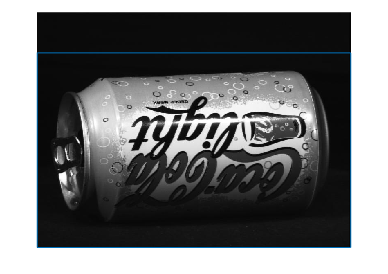

hold on
line(box(:, 1), box(:, 2))

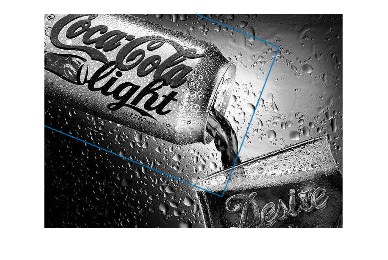


nbox = transformPointsForward(T, box);
figure, imshow(im_esc)
hold on
line(nbox(:, 1), nbox(:, 2))

## Detecció altres imatges

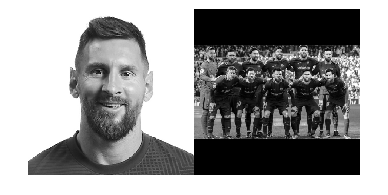

close all

% Carreguem les imatges
im_obj = rgb2gray(imread("messi.jpg"));
im_esc = rgb2gray(imread("escena_messi.jpg"));

% Les visualitzem
montage({im_obj, im_esc});

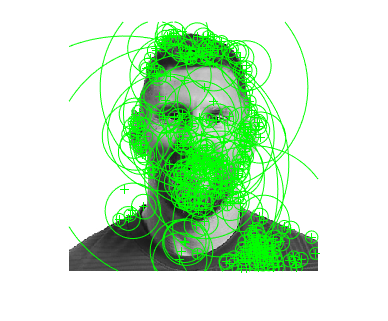


% Detectem features per SIFT
kp_obj = detectSIFTFeatures(im_obj);
kp_esc = detectSIFTFeatures(im_esc);

% Filtrem pels més "forts"
%kp_obj = selectStrongest(kp_obj, 30);
%kp_esc = selectStrongest(kp_esc, 200);

% Visualitzem els punts trobats a les dues imatges
figure, imshow(im_obj);
hold on;
plot(kp_obj);
hold off

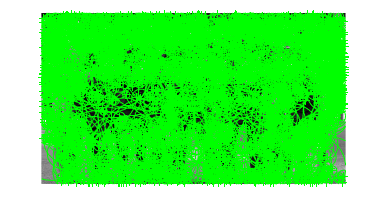

figure, imshow(im_esc);
hold on;
plot(kp_esc);
hold off;

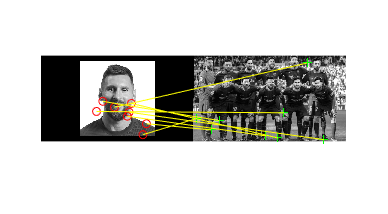



[feat_obj, kp_obj] = extractFeatures(im_obj, kp_obj);
[feat_esc, kp_esc] = extractFeatures(im_esc, kp_esc);

pairs = matchFeatures(feat_obj, feat_esc, "MatchThreshold", 10);

m_kp_obj = kp_obj(pairs(:, 1), :);
m_kp_esc = kp_esc(pairs(:, 2), :);

showMatchedFeatures(im_obj, im_esc, m_kp_obj, m_kp_esc, "montage")

[T] = estimateGeometricTransform2D(m_kp_obj, m_kp_esc, "affine");

[f_obj, c_obj] = size(im_obj);

box = [1, 100; c_obj, 100; c_obj, f_obj; 1, f_obj; 1, 100];
figure, imshow(im_obj)

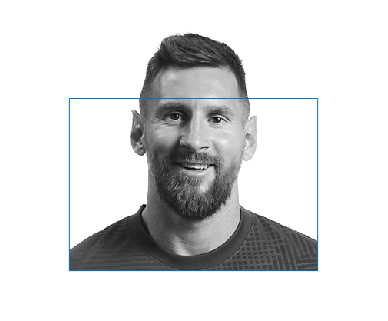

hold on
line(box(:, 1), box(:, 2))

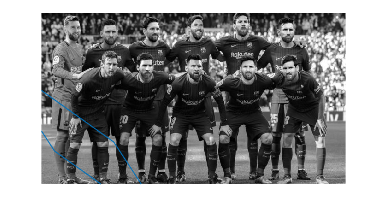


nbox = transformPointsForward(T, box);
figure, imshow(im_esc)
hold on
line(nbox(:, 1), nbox(:, 2))